# Data Visualization

## Preparation

clc, clear
close all

Datasetfolder ='./Experience1/Dataset';
files = dir(fullfile(Datasetfolder,'*.mat'));
data = load(fullfile(Datasetfolder,files(end).name));
u = single(data.u);

%% Spatial Mesh
% x
L_x = 3;                           % Maximum value in spatial direction
dx = 0.01;                         % Spatial displacement
N_x = floor(L_x/dx);               % Total number of spatial mesh
X_c = linspace(0,L_x,N_x);         % Coordinates (plot:N_x,range[0 L_x])
% y(same as x)
L_y = 3;
dy = 0.01;
N_y = floor(L_y/dy);
Y_c = linspace(0,L_y,N_y);

[X, Y] = meshgrid(X_c, Y_c);

%% Temporal Mesh
L_t = 7;                           % Maximum value in spatial direction
dt = 0.01;                         % Temporal displacement
N_t = floor(L_t/dt);               % Total number of temporal mesh

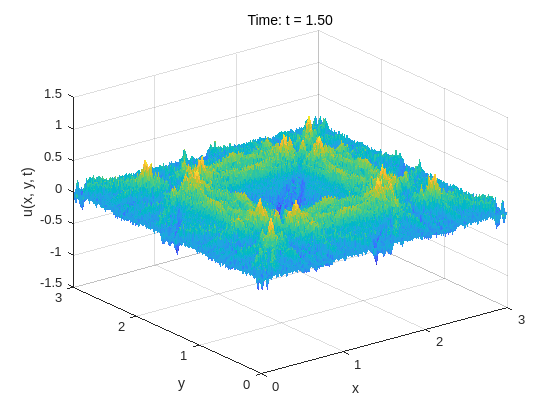


[Xs, Ys] = meshgrid(X_c, Y_c);

%% Data Extraction
T_st = 1;
T_en = 150;

for n = 1:size(u,3)
    surf(Ys, Xs, u(:, :, n)', 'EdgeColor', 'none');
    axis([0 L_x 0 L_y -1.5 1.5]);
    xlabel('x');
    ylabel('y');
    zlabel('u(x, y, t)');
    title(sprintf('Time: t = %.2f', (T_st - 1 + n)*dt));
    pause(0.01);
end